# Question 1


$$f1=2y\\
f2=x\\
f3=z$$


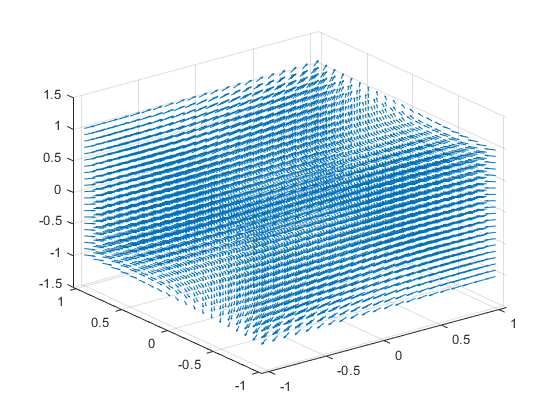

[X, Y, Z] = meshgrid(-1:0.1:1, -1:0.1:1, -1:0.1:1);

f1 = 2 * Y;
f2 = X;
f3 = Z;

quiver3(X, Y, Z, f1, f2, f3);

# Question 2


$$f = (x\cos{xe^x})i+(y\sin{x})j+(x^2z)k$$


[X, Y, Z] = meshgrid(-1:0.2:1, -1:0.2:1, -1:0.2:1);

f1 = X.*cos(X.*exp(X));
f2 = Y.*sin(X);
f3 = X.^2.*Z;

quiver3(X, Y, Z, f1, f2, f3);

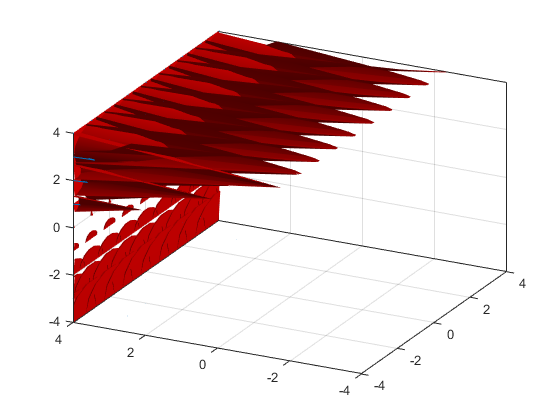

%% quiver plot
[x, y, z] = meshgrid(-4:1:4, -4:1:4, -4:1:4);
u = (y.^3).*sin(x)+z.^5;
v = 3.*(y.^2).*cos(x)-7.*exp(7.*y).*z;
w = 5.*x.*(z.^4)+exp(7.*y);

quiver3(x, y, z, u, v, w);

[cx, cy, cz] = meshgrid(-4:1:4, -4:1:4, -4:1:4);
h = coneplot(x, y, z, u, v, w, cx, cy, cz, 5);
set(h, 'FaceColor', 'r', 'EdgeColor', 'none');
camlight; lighting gouraud;

grid on; box on;
axis([-4 4 -4 4 -4 4]);
view(-30, 60);


%% streamline plot
clf;
clear all;

[x, y, z] = meshgrid(-4:1:4, -4:1:4, -4:1:4);
u = y.^3.*sin(x)+z.^5;
v = 3.*y.^2.*cos(x)-7.*exp(7.*y).*z;
w = 5.*x.*z.^4+exp(7.*y);

[sx,sy,sz] = meshgrid(-1.5, -1:1, -1:1);
hhh = streamline(x, y, z, u, v, w, -1, 1, -1.5);
hold on;
plot3(sx(:), sy(:), sz(:), 'bo', 'MarkerFaceColor', 'b')
grid on; box on;
view(-30, 60);

%% stream slice
clf;
clear all;

[x, y, z] = meshgrid(-4:1:4, -4:1:4, -4:1:4);
u = y.^3.*sin(x)+z.^5;
v = 3.*y.^2.*cos(x)-7.*exp(7.*y).*z;
w = 5.*x.*z.^4+exp(7.*y);

streamslice(x, y, z, u, v, w, 4, 4, -4);
box on;
axis([-4 4 -4 4 -4 4]);
view(-30, 60);

%% stream tubes
clf;
clear all;

[x, y, z] = meshgrid(-4:1:4);
u = y.^3.*sin(x)+z.^5;
v = 3.*y.^2.*cos(x)-7.*exp(7.*y).*z;
w = 5.*x.*z.^4+exp(7.*y);

[sx, sy, sz] = meshgrid(-4, -2:2, -2:2);  % stream starting point

% streamtube
subplot(121);
streamtube(x, y, z, u, v, w, sx, sy, sz);
shading interp
axis([-4 4 -4 4 -4 4]);
camlight; lighting gouraud
grid on;
title('streamtube');

% streamribbon
subplot(122);
streamribbon(x, y, z, u, v, w, sx, sy, sz);
shading interp
axis([-4 4 -4 4 -4 4]);
camlight headlight; camlight right; lighting gouraud
grid on;
title('streamribbon');
